clear ;
close all;

ecg = load('ecg_hfn.dat');
fs = 1000;

Perform (time) synchronous averaging to a noisy ECG signal and compare signal-to-noise ratio (SNR).

Select a QRS complex from the signal as template and use a suitable threshold on cross-correlation function for beat detection

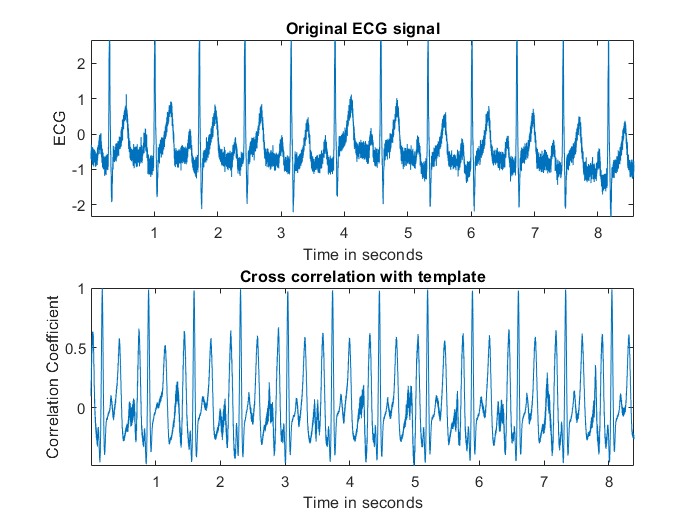

slen = length(ecg);
t=(1:slen)/fs;
figure(1);
subplot(211);
plot(t,ecg);axis tight;
xlabel('Time in seconds');ylabel('ECG');title('Original ECG signal');
temp=ecg(175:353);
for i=1:1:length(ecg)-length(temp)
   R=corrcoef(temp,ecg(i:i+length(temp)-1)); 
   Co(i)=R(3);
end
t2=(1:length(Co))/fs;
subplot(212);plot(t2,Co);axis tight;
ylabel('Correlation Coefficient');xlabel('Time in seconds');title('Cross correlation with template');

Heart beat detection

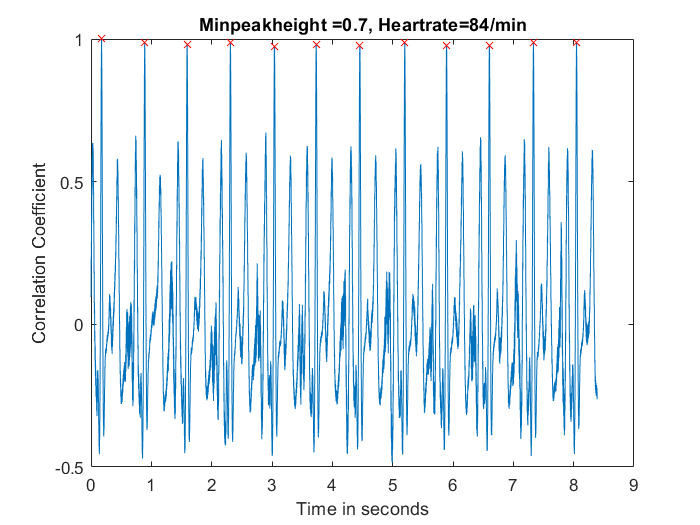

[pks,loc]=findpeaks(Co,'minpeakheight',0.7);
loc=loc/fs;
figure(2);
plot(t2,Co,loc,pks,'rx');
xlabel('Time in seconds');ylabel('Correlation Coefficient');
rate=round(length(loc)*60/t(end));title(['Minpeakheight =0.7, Heartrate=',num2str(rate),'/min']);

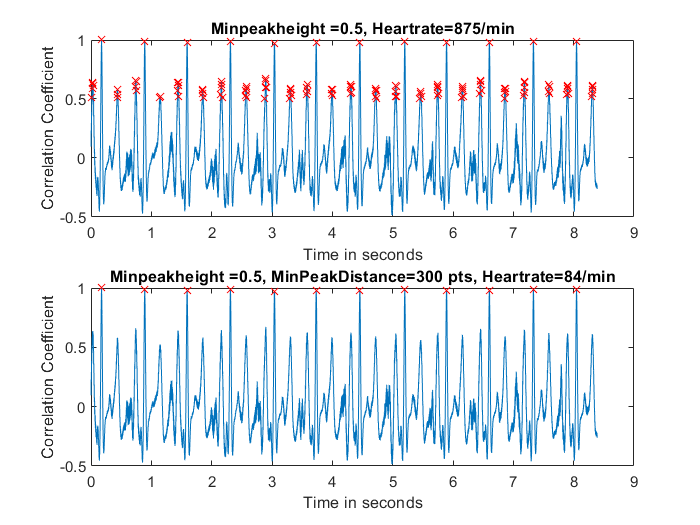

figure;subplot(211);
[pks,loc]=findpeaks(Co,'minpeakheight',0.5);
loc=loc/fs;
plot(t2,Co,loc,pks,'rx');
xlabel('Time in seconds');ylabel('Correlation Coefficient');
rate=round(length(loc)*60/t(end));title(['Minpeakheight =0.5, Heartrate=',num2str(rate),'/min']);

subplot(212);[pks,loc]=findpeaks(Co,'minpeakheight',0.5,'minpeakdistance',300);
loc=loc/fs;plot(t2,Co,loc,pks,'rx');
rate=round(length(loc)*60/t(end));
xlabel('Time in seconds');ylabel('Correlation Coefficient');title(['Minpeakheight =0.5, MinPeakDistance=300 pts, Heartrate=',num2str(rate),'/min']);

Original vs. Synchronized averaged ECG cycle with SNR

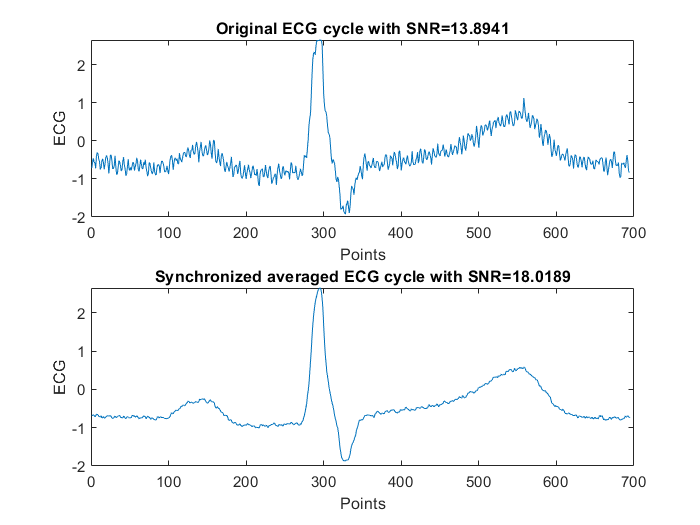

[pks3,loc3]=findpeaks(ecg,'minpeakheight',2.5,'MinPeakDistance',10); 
for i=1:12
    F=loc3(i)-294;
    T=loc3(i)+400;
    Seg(i,:)=ecg(F:T);
end
M=mean(Seg);figure;
subplot(211);plot(ecg(1:694));SNR=snr(ecg(1:694));
xlabel('Points');ylabel('ECG');title(['Original ECG cycle with SNR=',num2str(SNR)]);
subplot(212);plot(M);SNR2=snr(M);
xlabel('Points');ylabel('ECG');title(['Synchronized averaged ECG cycle with SNR=',num2str(SNR2)]);

*Perform moving average*

By 2 points

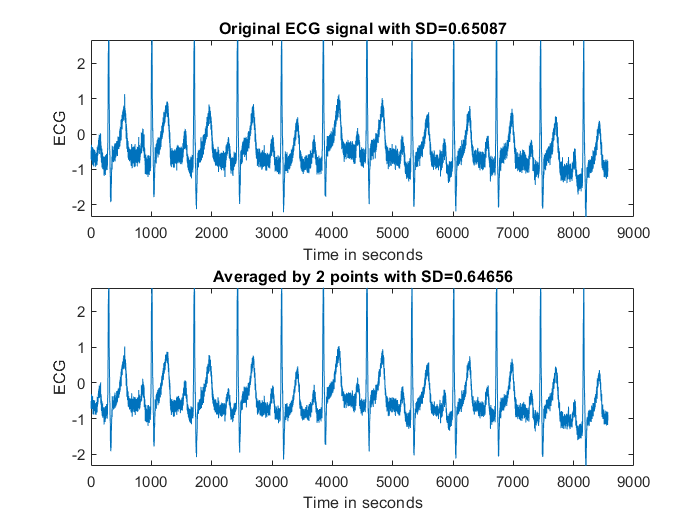

M1= movmean( ecg , 2 );
figure;subplot(211);plot(ecg);
xlabel('Time in seconds');ylabel('ECG');title(['Original ECG signal with SD=',num2str(std(ecg))]);
subplot(212);plot(M1);
xlabel('Time in seconds');ylabel('ECG');title(['Averaged by 2 points with SD=',num2str(std(M1))]);

By 4 points

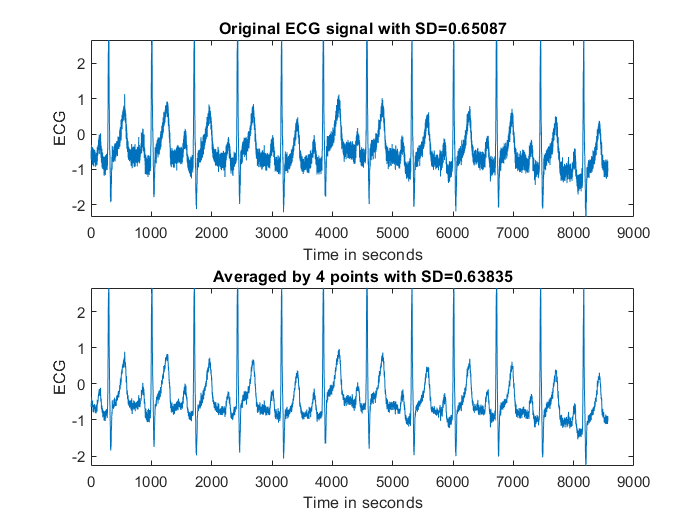

M2= movmean( ecg , 4 );
figure;subplot(211);plot(ecg);
xlabel('Time in seconds');ylabel('ECG');title(['Original ECG signal with SD=',num2str(std(ecg))]);
subplot(212);plot(M2);
xlabel('Time in seconds');ylabel('ECG');title(['Averaged by 4 points with SD=',num2str(std(M2))]);

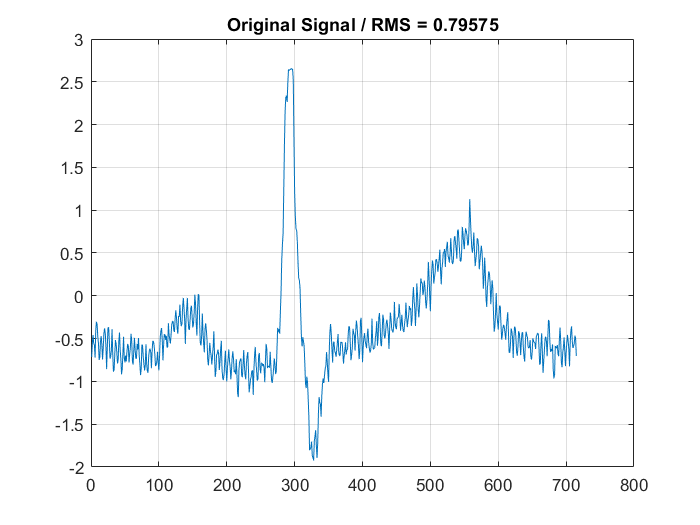

figure;
in=ecg(1:715);
plot(in);grid on;title(['Original Signal / RMS = ',num2str(rms(ecg))]);

Piece-wise model

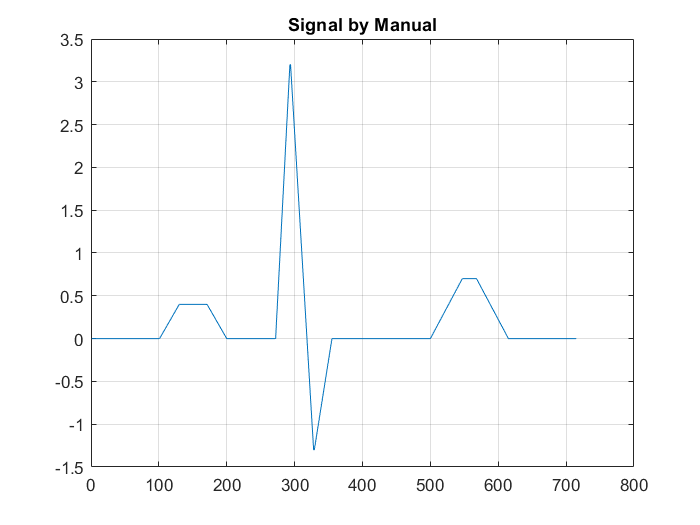

pw=zeros(1,715);
pw(101:130)=linspace(0,0.4,30);
pw(131:170)=0.4;
pw(171:200)=linspace(0.4,0,30);
pw(272:293)=linspace(0,3.2,22);
pw(294:328)=linspace(3.2,-1.3,35);
pw(329:355)=linspace(-1.3,0,27);
pw(500:547)=linspace(0,0.7,48);
pw(548:567)=0.7;
pw(568:615)=linspace(0.7,0,48);
figure;
plot(pw);grid on;title('Signal by Manual');

Wiener filter

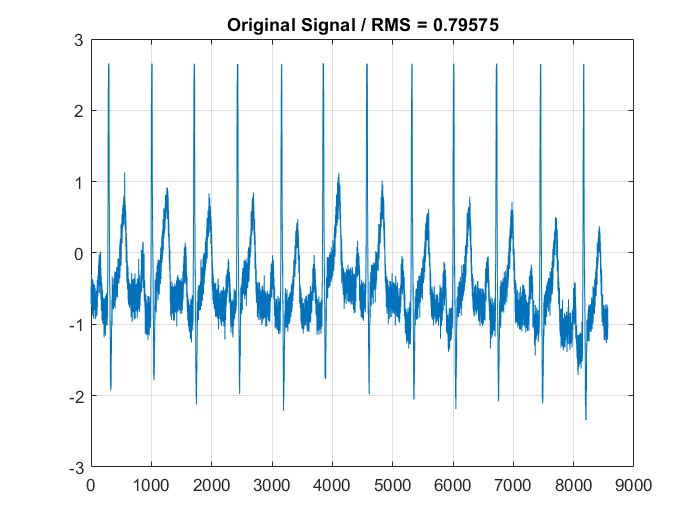

N=715;
rxx = xcorr(ecg,N,'coeff');
rxx = rxx(N+1:end-1)'; 
rxy = xcorr(ecg,pw,N);
rxy = rxy(N+1:end-1);
rxx_matrix = toeplitz(rxx);
b = rxx_matrix\rxy;
b=b/N;
y=conv(b,ecg);
figure;

plot(ecg);grid on;title(['Original Signal / RMS = ',num2str(rms(ecg))]);

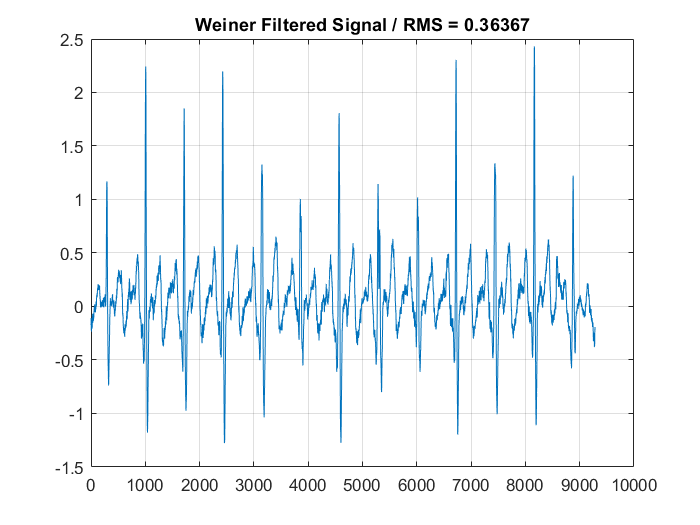

figure;
plot(y);grid on;title(['Weiner Filtered Signal / RMS = ',num2str(rms(y))]);

Low Pass Filter

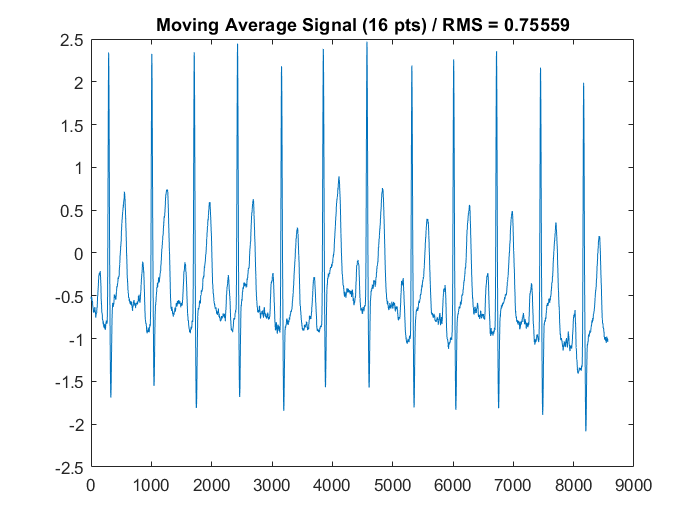

d=movmean(ecg,16);
figure;
plot(d);title(['Moving Average Signal (16 pts) / RMS = ',num2str(rms(d))]);

PSD of model

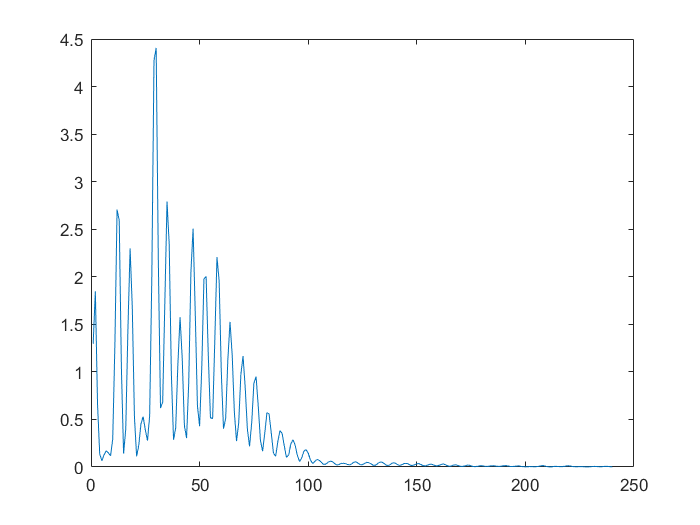

Pxx=pwelch(y);
figure;
plot(Pxx(1:240));

FFT

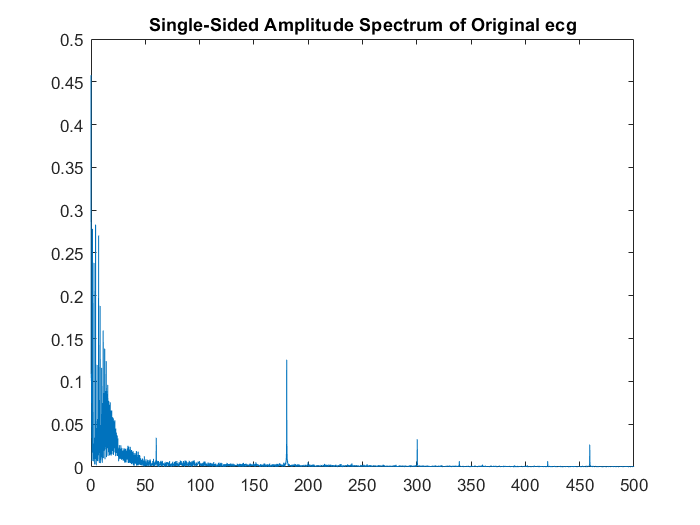

fs=1000;
L=length(ecg);f = fs*(0:(L/2))/L;
Y = fft(ecg);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
figure;plot(f,P1);title('Single-Sided Amplitude Spectrum of Original ecg');